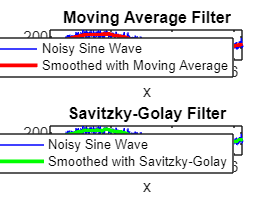

% Number of points
N = 1000;

% Generate the x-axis values (one complete cycle)
x = linspace(0, 2*pi, N);

% Generate the sine wave
y = sin(x);
y = (y-min(y))/(max(y)-min(y))*255;

% Add random noise to the sine wave
noiseAmplitude = 30;
noise = noiseAmplitude * randn(size(y));
yNoisy = y + noise;
% Normalize the values to the range [0, 1]
yNoisy = (yNoisy - min(yNoisy)) / (max(yNoisy) - min(yNoisy));
% Scale the values to the range [0, 255]
yNoisy = int16(yNoisy * 255);
writematrix(yNoisy', "data_matlab.csv");

% Define the window size for the moving average
windowSizeMA = 50;  % Adjust based on desired smoothness

% Apply the moving average filter using built-in function
ySmoothedMA = smoothdata(yNoisy, 'movmean', windowSizeMA);

% Define the window size and polynomial degree for the Savitzky-Golay filter
windowSizeSG = 51;  % Must be odd
polyOrder = 3;      % Typical values are 2, 3, 4

% Apply the Savitzky-Golay filter using built-in function
ySmoothedSG = smoothdata(yNoisy, 'sgolay', windowSizeSG, 'Degree', polyOrder);

% Plot the results in two subplots
figure;
subplot(2,1,1);  % First subplot for Moving Average
plot(x, yNoisy, 'b-', 'DisplayName', 'Noisy Sine Wave');
hold on;
plot(x, ySmoothedMA, 'r-', 'LineWidth', 2, 'DisplayName', 'Smoothed with Moving Average');
legend show;
xlabel('x');
ylabel('y');
title('Moving Average Filter');

subplot(2,1,2);  % Second subplot for Savitzky-Golay
plot(x, yNoisy, 'b-', 'DisplayName', 'Noisy Sine Wave');
hold on;
plot(x, ySmoothedSG, 'g-', 'LineWidth', 2, 'DisplayName', 'Smoothed with Savitzky-Golay');
legend show;
xlabel('x');
ylabel('y');
title('Savitzky-Golay Filter');

filename = 'output.csv';
output = readmatrix(filename)';
%y = y(1:949);
y = y;
noise = output - y;

% Calculate Signal-to-Noise Ratio (SNR)
signalPowerSG = bandpower(y);
noisePowerSG = bandpower(noise);
SNR_SG = 10 * log10(signalPowerSG / noisePowerSG)

SNR_SG = 9.0938


% Calculate Mean Squared Error (MSE)
MSE_SG = immse(output,y)

MSE_SG = 3.0032e+03